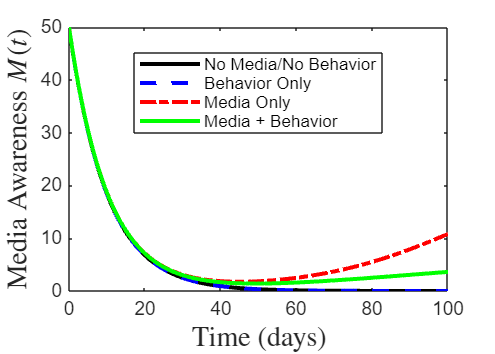

% ==============================================================
% EFFECT OF MEDIA AND HUMAN BEHAVIOR ON DISEASE DYNAMICS
% ==============================================================

clear; clc; close all;

% Parameters
par.psi     = 0.015;
par.K       = 22000;
par.mu      = 0.001;

par.delta1  = 0.0008;
par.p3      = 5000;

par.alpha_b = 0.005;
par.Kb      = 1200;

par.betaQ   = 0.00005;

par.epsilon = 0.013;

par.phi     = 0.05;
par.eta     = 0.0010;       % <<< BASELINE removal rate

par.rho     = 0.30;
par.sigma   = 0.001;

par.alpha   = 0.4211;
par.muL     = 0.2;
par.sigmaL  = 0.4;
par.deltaQ  = 0.5;

par.kappa   = 0.2;
par.xi      = 0.1;

% Initial conditions
S0  = 20500;
E0  = 100;
I0  = 50;
R0  = 0;

LF0 = 10;
Q0  = 5;

% Recommended value
M0  = 50;

y0 = [S0 E0 I0 R0 LF0 Q0 M0];

% Time span
tspan = [0 100];

% ============================================================
% Scenario 1: No Media, No Behavior
% ============================================================
par1 = par;
par1.rhoM  = 0;
par1.gamma = 0;
par1.kappa = 0;

[t1,y1] = ode45(@(t,y)diseaseModel(t,y,par1),tspan,y0);

% ============================================================
% Scenario 2: Behavior Only
% ============================================================
par2 = par;
par2.rhoM  = 0;
par2.gamma = 0.001;
par2.kappa = 0;

[t2,y2] = ode45(@(t,y)diseaseModel(t,y,par2),tspan,y0);

% ============================================================
% Scenario 3: Media Only
% ============================================================
par3 = par;
par3.rhoM  = 0.001;
par3.gamma = 0;
par3.kappa = 0.001;

[t3,y3] = ode45(@(t,y)diseaseModel(t,y,par3),tspan,y0);

% ============================================================
% Scenario 4: Media + Behavior
% ============================================================
par4 = par;
par4.rhoM  = 0.001;
par4.gamma = 0.001;
par4.kappa = 0.001;

[t4,y4] = ode45(@(t,y)diseaseModel(t,y,par4),tspan,y0);

% ============================================================
% Media Dynamics
% ============================================================
figure('Color','w','Position',[100 100 700 500])
plot(t1,y1(:,7),'k','LineWidth',2); hold on
plot(t2,y2(:,7),'b--','LineWidth',2)
plot(t3,y3(:,7),'r-.','LineWidth',2)
plot(t4,y4(:,7),'g','LineWidth',2)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Media Awareness $M(t)$', 'Interpreter', 'latex', 'FontSize', 14)
legend('No Media/No Behavior',...
       'Behavior Only',...
       'Media Only',...
       'Media + Behavior',...
       'Location','best')
box on; 

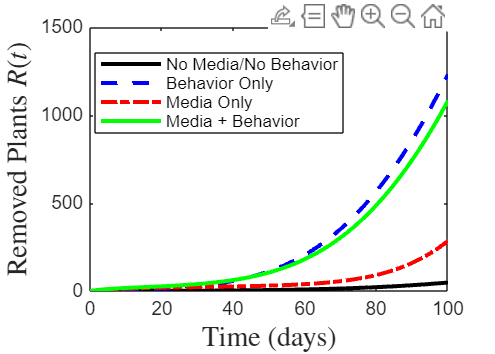

%grid on;

% ============================================================
% Removed Population
% ============================================================
figure('Color','w','Position',[150 150 700 500])
plot(t1,y1(:,4),'k','LineWidth',2); hold on
plot(t2,y2(:,4),'b--','LineWidth',2)
plot(t3,y3(:,4),'r-.','LineWidth',2)
plot(t4,y4(:,4),'g','LineWidth',2)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Removed Plants $R(t)$', 'Interpreter', 'latex', 'FontSize', 14)
legend('No Media/No Behavior',...
       'Behavior Only',...
       'Media Only',...
       'Media + Behavior',...
       'Location','best')
box on; 

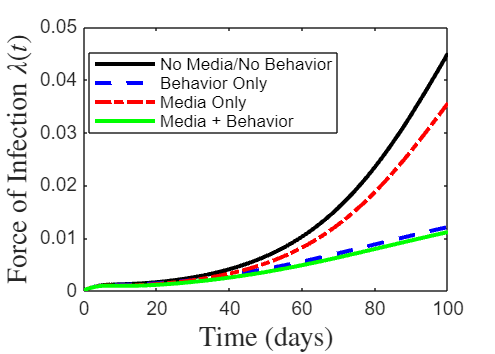

%grid on;

% ============================================================
% Force of Infection
% ============================================================
lambda1 = zeros(length(t1),1);
lambda2 = zeros(length(t2),1);
lambda3 = zeros(length(t3),1);
lambda4 = zeros(length(t4),1);

for k = 1:length(t1)
    N = sum(y1(k,1:4));
    lambda1(k) = par1.delta1 ...
        *(par1.p3/(par1.p3+y1(k,7))) ...
        *(1-par1.alpha_b*y1(k,7)/(par1.Kb+y1(k,7))) ...
        *(y1(k,3)/N) ...
        + par1.betaQ*y1(k,6);
end

for k = 1:length(t2)
    N = sum(y2(k,1:4));
    lambda2(k) = par2.delta1 ...
        *(par2.p3/(par2.p3+y2(k,7))) ...
        *(1-par2.alpha_b*y2(k,7)/(par2.Kb+y2(k,7))) ...
        *(y2(k,3)/N) ...
        + par2.betaQ*y2(k,6);
end

for k = 1:length(t3)
    N = sum(y3(k,1:4));
    lambda3(k) = par3.delta1 ...
        *(par3.p3/(par3.p3+y3(k,7))) ...
        *(1-par3.alpha_b*y3(k,7)/(par3.Kb+y3(k,7))) ...
        *(y3(k,3)/N) ...
        + par3.betaQ*y3(k,6);
end

for k = 1:length(t4)
    N = sum(y4(k,1:4));
    lambda4(k) = par4.delta1 ...
        *(par4.p3/(par4.p3+y4(k,7))) ...
        *(1-par4.alpha_b*y4(k,7)/(par4.Kb+y4(k,7))) ...
        *(y4(k,3)/N) ...
        + par4.betaQ*y4(k,6);
end

figure('Color','w','Position',[200 200 700 500])
plot(t1,lambda1,'k','LineWidth',2); hold on
plot(t2,lambda2,'b--','LineWidth',2)
plot(t3,lambda3,'r-.','LineWidth',2)
plot(t4,lambda4,'g','LineWidth',2)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Force of Infection $\lambda(t)$', 'Interpreter', 'latex', 'FontSize', 14)
legend('No Media/No Behavior',...
       'Behavior Only',...
       'Media Only',...
       'Media + Behavior',...
       'Location','best')
box on; 

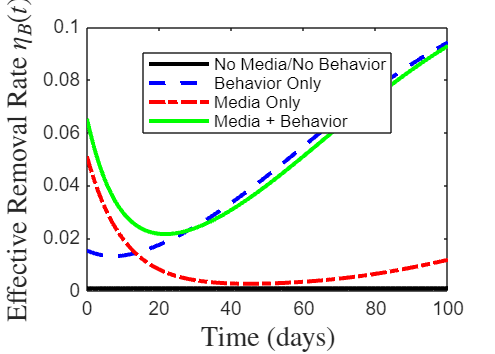

%grid on;

% ============================================================
% TOTAL EFFECTIVE REMOVAL RATE  eta_B = eta + rhoM*M + gamma*u_b(I)
% ============================================================
etaB1 = par1.eta + par1.rhoM*y1(:,7) ...
      + par1.gamma*(par1.rho*y1(:,3)./(1+par1.sigma*y1(:,3)));

etaB2 = par2.eta + par2.rhoM*y2(:,7) ...
      + par2.gamma*(par2.rho*y2(:,3)./(1+par2.sigma*y2(:,3)));

etaB3 = par3.eta + par3.rhoM*y3(:,7) ...
      + par3.gamma*(par3.rho*y3(:,3)./(1+par3.sigma*y3(:,3)));

etaB4 = par4.eta + par4.rhoM*y4(:,7) ...
      + par4.gamma*(par4.rho*y4(:,3)./(1+par4.sigma*y4(:,3)));

figure('Color','w','Position',[250 250 700 500])
plot(t1,etaB1,'k','LineWidth',2); hold on
plot(t2,etaB2,'b--','LineWidth',2)
plot(t3,etaB3,'r-.','LineWidth',2)
plot(t4,etaB4,'g','LineWidth',2)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Effective Removal Rate $\eta_B(t)$', 'Interpreter', 'latex', 'FontSize', 14)
legend('No Media/No Behavior',...
       'Behavior Only',...
       'Media Only',...
       'Media + Behavior',...
       'Location','best')
box on; 

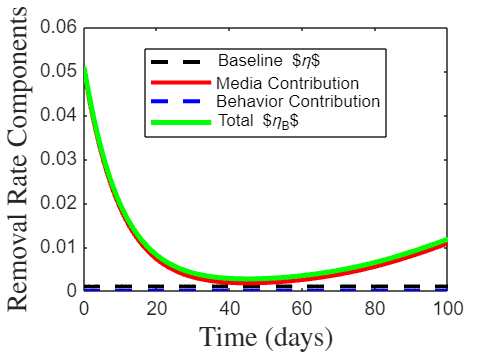

%grid on;

% ============================================================
% Media Contribution vs Human Behavior Contribution (Scenario 3)
% ============================================================
baselineEta    = par3.eta * ones(size(t3));
mediaEffect    = par3.rhoM*y3(:,7);
behaviorEffect = par3.gamma*(par3.rho*y3(:,3)./(1+par3.sigma*y3(:,3)));

figure('Color','w','Position',[300 300 700 500])
plot(t3,baselineEta,'k--','LineWidth',2); hold on
plot(t3,mediaEffect,'r','LineWidth',2)
plot(t3,behaviorEffect,'b--','LineWidth',2)
plot(t3,baselineEta + mediaEffect + behaviorEffect,...
    'g','LineWidth',2.5)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Removal Rate Components', 'Interpreter', 'latex', 'FontSize', 14)
legend('Baseline $\eta$',...
       'Media Contribution',...
       'Behavior Contribution',...
       'Total $\eta_B$',...
       'Location','best')
box on; 

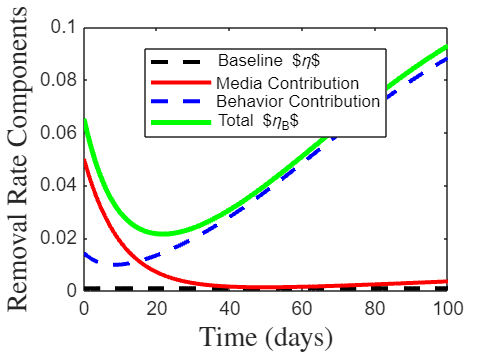

%grid on;

% ============================================================
% Media Contribution vs Human Behavior Contribution (Scenario 4)
% ============================================================
baselineEta    = par4.eta * ones(size(t4));
mediaEffect    = par4.rhoM*y4(:,7);
behaviorEffect = par4.gamma*(par4.rho*y4(:,3)./(1+par4.sigma*y4(:,3)));

figure('Color','w','Position',[350 350 700 500])
plot(t4,baselineEta,'k--','LineWidth',2); hold on
plot(t4,mediaEffect,'r','LineWidth',2)
plot(t4,behaviorEffect,'b--','LineWidth',2)
plot(t4,baselineEta + mediaEffect + behaviorEffect,...
     'g','LineWidth',2.5)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Removal Rate Components', 'Interpreter', 'latex', 'FontSize', 14)
legend('Baseline $\eta$',...
       'Media Contribution',...
       'Behavior Contribution',...
       'Total $\eta_B$',...
       'Location','best')
box on; 

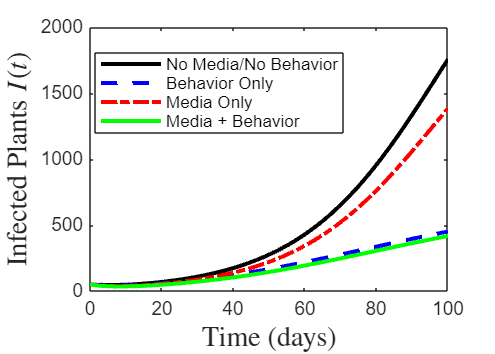

%grid on;

% ============================================================
% Behavioral removal rates  (total eta_B for each scenario)
% ============================================================
B1 = par1.eta + par1.gamma*(par1.rho*y1(:,3)./(1+par1.sigma*y1(:,3))) ...
   + par1.rhoM*y1(:,7);

B2 = par2.eta + par2.gamma*(par2.rho*y2(:,3)./(1+par2.sigma*y2(:,3))) ...
   + par2.rhoM*y2(:,7);

B3 = par3.eta + par3.gamma*(par3.rho*y3(:,3)./(1+par3.sigma*y3(:,3))) ...
   + par3.rhoM*y3(:,7);

B4 = par4.eta + par4.gamma*(par4.rho*y4(:,3)./(1+par4.sigma*y4(:,3))) ...
   + par4.rhoM*y4(:,7);

% ============================================================
% Figure 1: Infection Dynamics
% ============================================================
figure('Color','w','Position',[400 100 700 500])
plot(t1,y1(:,3),'k','LineWidth',2); hold on
plot(t2,y2(:,3),'b--','LineWidth',2)
plot(t3,y3(:,3),'r-.','LineWidth',2)
plot(t4,y4(:,3),'g','LineWidth',2)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Infected Plants $I(t)$', 'Interpreter', 'latex', 'FontSize', 14)
legend('No Media/No Behavior',...
       'Behavior Only',...
       'Media Only',...
       'Media + Behavior',...
       'Location','best')
box on; 

%grid on;

% ============================================================
% Figure 2: Media Awareness
% ============================================================
figure('Color','w','Position',[450 150 700 500])
plot(t1,y1(:,7),'k','LineWidth',2); hold on
plot(t2,y2(:,7),'b--','LineWidth',2)
plot(t3,y3(:,7),'r-.','LineWidth',2)
plot(t4,y4(:,7),'g','LineWidth',2)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Media Awareness $M(t)$', 'Interpreter', 'latex', 'FontSize', 14) % FIXED: Was just $M(t)$
legend('No Media/No Behavior',...
       'Behavior Only',...
       'Media Only',...
       'Media + Behavior',...
       'Location','best')
box on; 

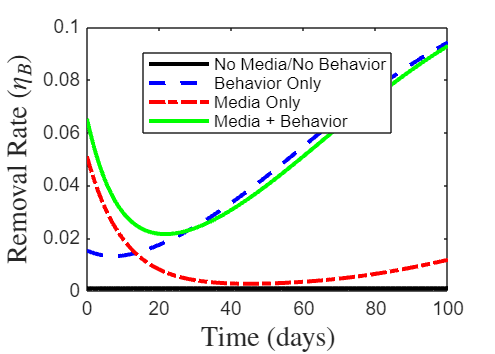

%grid on;

% ============================================================
% Figure 3: Total Effective Removal Rate  eta_B(t)
% ============================================================
figure('Color','w','Position',[500 200 700 500])
plot(t1,B1,'k','LineWidth',2); hold on
plot(t2,B2,'b--','LineWidth',2)
plot(t3,B3,'r-.','LineWidth',2)
plot(t4,B4,'g','LineWidth',2)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Removal Rate ($\eta_B)$', 'Interpreter', 'latex', 'FontSize', 14) % FIXED: Was 'Removal Rate'
legend('No Media/No Behavior',...
       'Behavior Only',...
       'Media Only',...
       'Media + Behavior',...
       'Location','best')
box on; 

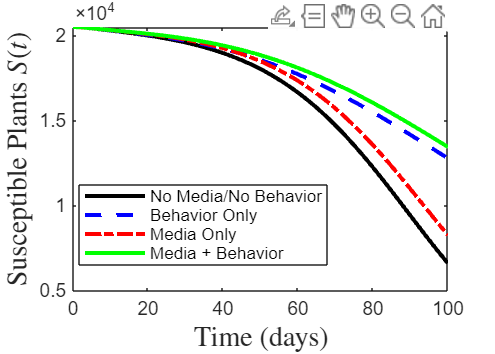

%grid on;

% ============================================================
% Figure: Susceptible Plants Dynamics
% ============================================================
figure('Color','w','Position',[550 250 700 500])
plot(t1,y1(:,1),'k','LineWidth',2); hold on
plot(t2,y2(:,1),'b--','LineWidth',2)
plot(t3,y3(:,1),'r-.','LineWidth',2)
plot(t4,y4(:,1),'g','LineWidth',2)
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Susceptible Plants $S(t)$', 'Interpreter', 'latex', 'FontSize', 14)
legend('No Media/No Behavior',...
       'Behavior Only',...
       'Media Only',...
       'Media + Behavior',...
       'Location','best')
box on; 

%grid on;

% ============================================================
% ODE SYSTEM  (unchanged — eta is already used correctly here)
% ============================================================
function dydt = diseaseModel(~,y,p)

S  = y(1);
E  = y(2);
I  = y(3);
R  = y(4);
LF = y(5);
Q  = y(6);
M  = y(7);

NT = S + E + I + R;

lambda = p.delta1 ...
    *(p.p3/(p.p3+M)) ...
    *(1-p.alpha_b*M/(p.Kb+M)) ...
    *(I/NT) ...
    + p.betaQ*Q;

% Additional removal due to media + behavior (on top of baseline eta)
B = p.gamma*(p.rho*I/(1+p.sigma*I)) ...
    + p.rhoM*M;

dS = p.psi*NT*(1-NT/p.K) ...
    - lambda*S ...
    - p.mu*S;

dE = lambda*S ...
    - (p.epsilon+p.mu)*E;

% Total removal from infected class = eta + B
dI = p.epsilon*E ...
    - (p.phi + p.eta + B + p.mu)*I;

dR = (p.eta + B)*I ...
    - p.mu*R;

dLF = p.alpha*I ...
    - (p.muL+p.sigmaL)*LF;

dQ = p.sigmaL*LF ...
    - p.deltaQ*Q;

dM = p.kappa*I ...
    - p.xi*M;

dydt = [dS; dE; dI; dR; dLF; dQ; dM];

end
